# Fluid descriptions

[⇦ Overview](matlab:open('./Overview.m'))

Fluid material are continuous substance composed of a very large number of particle that do not display of fixed shape. Both liquids and gases are generics type of fluids that diplay one major difference. Gas 

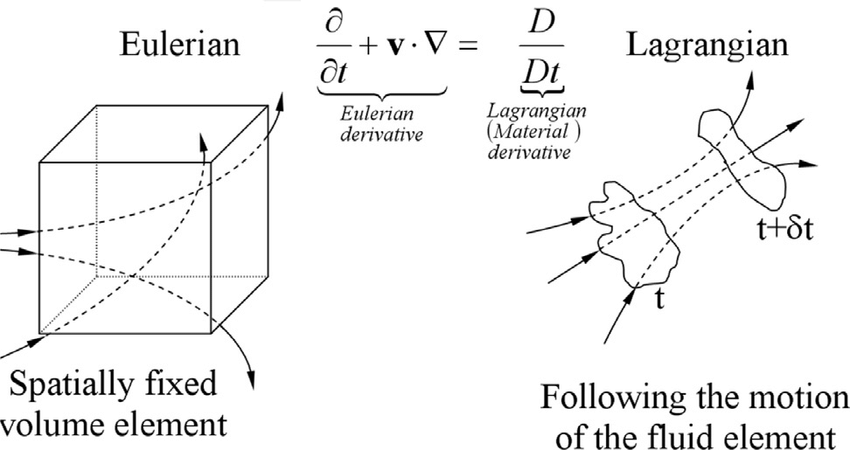

Conservation law: in an isolated system, measurable physical property does not change as the system evolves with time.

## Icon that can be used

  **Try**.

  **Pro-tip**.

** Demonstration**.

 **Reflect**.

** Application.**

## Notation

Define all of the notation that will be used in this module/scripts:

Partial derivative:


$$\begin{array}{l}
f\left(x,y\right)\\
\frac{\partial f\;}{\partial x}=\lim_{h\to 0} \frac{\;f\left(x+h,y\right)-f\left(x,y\right)}{h}
\end{array}$$


The gradient operator (e.i. derivate of physical measurement with respect to space);

1D: $\nabla \equiv \frac{\;\partial \;}{\partial x\;}$

2D: $\nabla \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial x\;}\\
\frac{\;\partial \;}{\partial y}
\end{array}\right\rbrack }_{\mathrm{carthesian}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial }{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}
\end{array}\right\rbrack }_{\mathrm{polar}}$

3D: $\nabla \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial x\;}\\
\frac{\;\partial \;}{\partial y}\\
\frac{\;\partial }{\partial z}
\end{array}\right\rbrack }_{\mathrm{carthesian}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial }{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}\\
\frac{\;\partial \;}{\partial z}
\end{array}\right\rbrack }_{\mathrm{cylindrical}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}\\
\frac{\;1}{\mathrm{rsin}\left(\theta \;\right)}\frac{\;\partial \;}{\partial \varphi \;\;}
\end{array}\right\rbrack }_{\mathrm{spherical}} \;$

$\mathit{\mathbf{u}}=\left\lbrack \begin{array}{c}
u_x \\
u_y \\
u_z 
\end{array}\right\rbrack$ bold notation for vector will be prefered over arrow superscript

## How to describe a fluid?

Let's start with tracking the position of a particle of fluid P of mass m with respect to time as it is experiencing only one force $F_p =\left\lbrack \begin{array}{c}
2*\cos \left(t\right)\\
\frac{1}{1+t}+0\ldotp 1*y
\end{array}\right\rbrack$

from mA = Sum(F)

syms x(t) y(t) m Fx(t) Fy(t) ux(t) uy(t) x0 y0
Fx(t) = 2*cos(5*t);
Fy(t) = 1/(1+t)-sin(3*t);
eqnx = m*diff(x(t), 2) == Fx(t);
ux(t) = diff(x(t), 1);
uy(t) = diff(y(t), 1);
eqny = m*diff(y(t), 2) == Fy(t);
eqns = [eqnx  eqny];

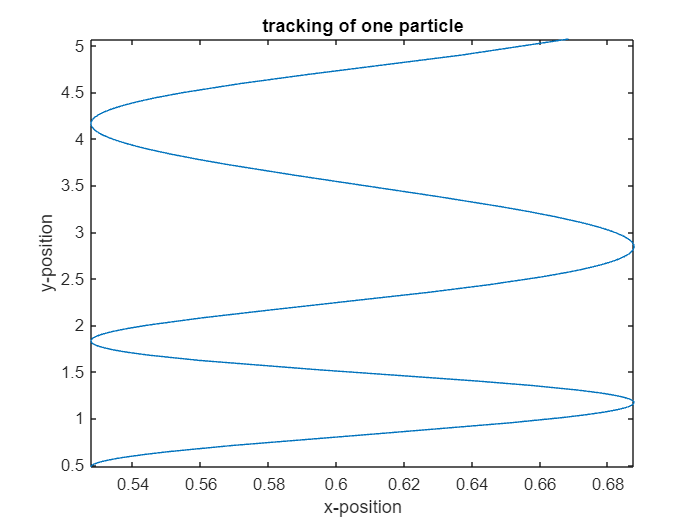

[x(t),y(t)] = dsolve(eqns, [x(0) == x0, y(0) == y0, ux(0) == 0, uy(0) == 1 ]);
xs(t) = subs(x(t),[m x0],[1 rand()]);
ys(t) = subs(y(t),[m y0],[1 rand()]);
fplot(xs(t),ys(t), [0 3])
xlabel("x-position")
ylabel("y-position")
title('tracking of one particle')

 **Reflect**. Tracking one particle would be really similar than classical solid mechanic. However fluid mechanics differ from solid mechanicis in the sense that fluid do not hold a constant shape and therefore we would need to track every (or most) particle to describe the fluid. In fact, we can define fluid parcel that are much larger than the molecule composing our gas or liquid but still very small. Let's see what it would take to track 50 of those particle with respect to time

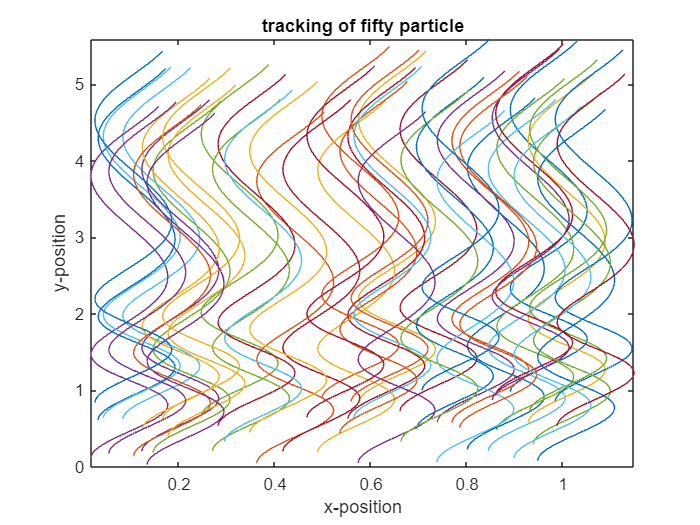

for i = 1:50
    xs(t) = subs(x(t),[m x0],[1 rand()]);
    ys(t) = subs(y(t),[m y0],[1 rand()]);
    fplot(xs(t),ys(t), [0 3])
    hold on
end
hold off
xlabel("x-position")
ylabel("y-position")
title('tracking of fifty particle')

** Application. **Weather balloon experiment are aiming at flowing in the atmosphere with the atmospheric fluid parcel and can track location, temperature, humity. etc. This type of experiment is Lagrangian by nature.

  **Pro-tip**. If there were only a few particle to track in time, such as in a billiard, Lagrangian description would be suitable. However, because of the very large number of particles to track in a fluid, Lagrangian formulation are rarely used. 

### Eulerian description of fluid

In Eulerian description of fluid, the physical properties of the fluid are not tracked on the particle themself rather they are tracked at fixed location in space. For example, when Lagrangian measurement in meteorology corresponds to atmospheric balloon, Eulerian measurement corresponds to placing thermometer, anemometer, barometer, etc. in fixed location in space.

Let's define a random field of velocity such as $\mathit{\mathbf{u}}=\left\lbrack \begin{array}{c}
0\ldotp 3\textrm{xy}-0\ldotp 1\\
0\ldotp 4\sqrt{x^2 +y^2 }
\end{array}\right\rbrack$

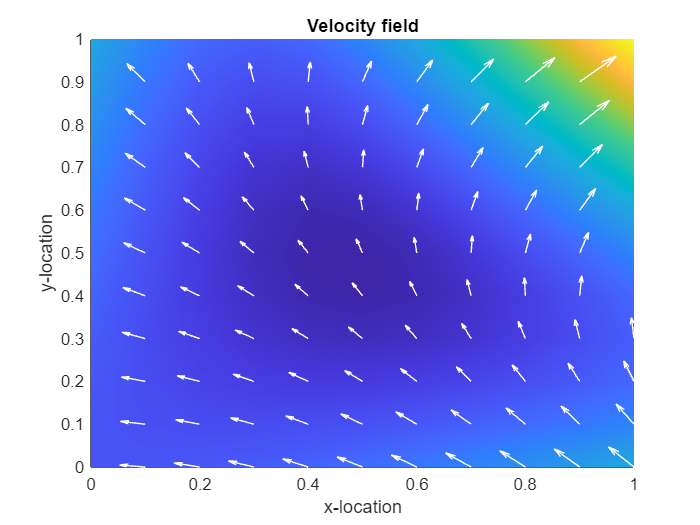

x = 0:0.1:1;
y = 0:0.1:1;
[xg, yg] = meshgrid(x,y);

ux = 1.2*xg.*yg-0.4;
uy = 0.4*sqrt(xg.^2+yg.^2);

figure()
hold on 
xlim([0 1])
ylim([0 1])

u = sqrt(ux.^2+uy.^2);
contourf(x,y,u,256, 'LineColor', 'none')
quiver(xg, yg, ux, uy, 'Color', 'w')
xlabel("x-location")
ylabel("y-location")
title("Velocity field")

## Link in between Eulerian and Lagrangian

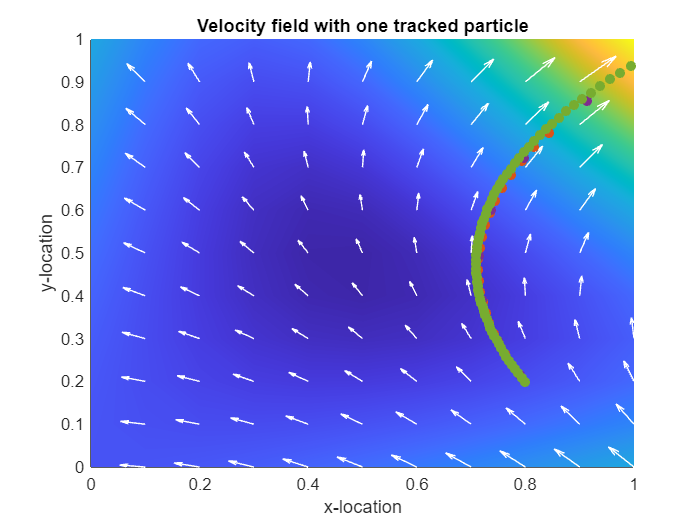

x0 = [0.8; 0.2];


dxdt = @(t, x) [interp2(xg, yg, ux, x(1), x(2)); interp2(xg, yg, uy, x(1), x(2))];

[t, y] = ode45(dxdt, [0 3], x0);
hold on
scatter(y(:,1), y(:,2), 'filled', 'SeriesIndex', 2) ;
hold off

[t, y] = ode23(dxdt, [0 3], x0);
hold on
scatter(y(:,1), y(:,2), 'filled', 'SeriesIndex', 4) ;
hold off

% Euler
t = 0.0;
hold on
for i = 1:100
    scatter(x0(1), x0(2), 'filled', 'SeriesIndex', 5);
    x0 = x0 + 0.03*dxdt(t, x0);
    t = t + 0.03;
end
hold off

xlabel("x-location")
ylabel("y-location")
title("Velocity field with one tracked particle")

## Derivative with respect to time

 **Reflect**. The second law of physics tell us $m\frac{\;\partial \mathit{\mathbf{u}}}{\partial t}=\mathit{\mathbf{F}}$

A    Phi(x,t)

B    Phi(x+u*dt, t+dt)

% syms Phi(x,t) u dx dt
% 
% dPhidt = limit( ( Phi(x+u*dt, t+dt) - Phi(x,t) )/dt, dt, 0 )



$$\frac{D\phi \;}{\textrm{Dt}}=\frac{\;\partial \phi \;}{\partial t}+\mathit{\mathbf{u}}\cdot \nabla \phi \;$$


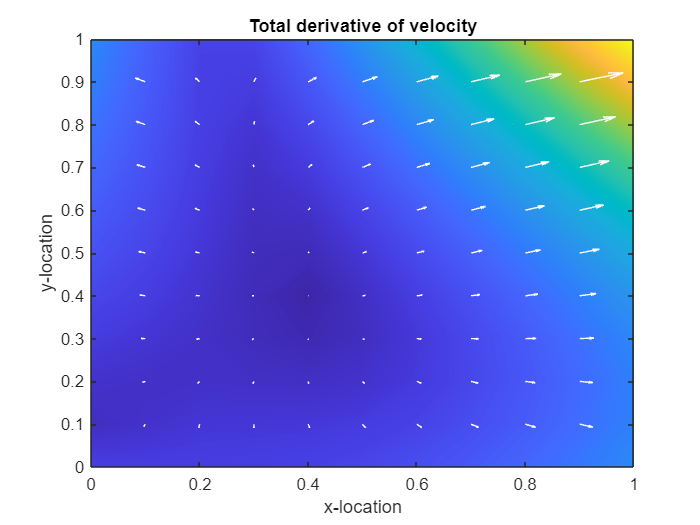

[graduxx, graduxy] = gradient(ux, 0.1);
[graduyx, graduyy] = gradient(uy, 0.1);
Ax = 0.0 + ux.*graduxx + uy.*graduxy;
Ay = 0.0 + ux.*graduyx + uy.*graduyy;
A  = sqrt(Ax.^2+Ay.^2);
contourf(xg, yg, A , 256, 'LineColor', 'none')
hold on
quiver(xg, yg, Ax, Ay, 'Color', 'w')
xlim([0 1])
ylim([0 1])
xlabel("x-location")
ylabel("y-location")
title("Total derivative of velocity")
hold off

 **Reflect**.This acceleration is the acceleration felt by the particle of fluid in this field of velocity. Newton's law $m\vec{a} =\sum \vec{\;F_{\textrm{ext}\;} }$

Physical properties of the system such as temperature, mass, density, or really anything is hold on the fluid particle wether than the grid.

## Reynolds Transport Theorem

So far we discussed how to describe the motion of the fluid particle


$$\int(\nabla\cdot {\bf F})dV=\int ({\bf F}\cdot{\bf n})dS$$


1 - Derive the Reynolds transport therorem

2 - Ask to apply the theorem to mass -> conservation of mass

3 - Conservation of energy?

% 

[⇦ Return to the navigation page](matlab: OpenOverview)